# Inversor de frecuencia para codificación de audio

### Taller II - Señales y Sistemas II

#### Sergio Andres Guevara Contreras

#### Eduardo Toro Bernal

#### Miguel Angel Bernal

### Universidad Nacional de Colombia

El siguiente diagrama presenta un esquema sencillo de un sistema inversor de frecuencia que se puede utilizar como codificador de audio: 

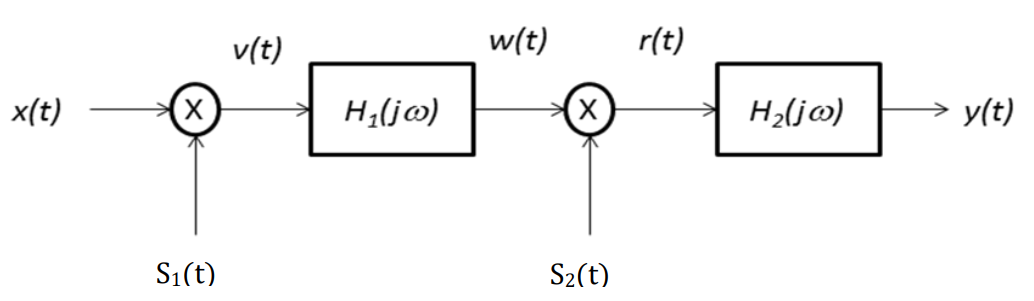

Las características del sistema son: 

- La señal S1 es un coseno a 120kHz.

- La señal S2 es un coseno a 96kHz. 

- El sistema H1 es un filtro pasabandas con frecuencias de corte 96kHz y 120kHz. 

- El sistema H2 es un filtro pasabajos con frecuencia de corte 48kHz.

Las características de los filtros son:

- Pasabanda: 3dB en las frecuencias de corte y una atenuación de 30dB a una octava de las frecuencias de corte. 

- Pasabajos: 3dB a 48kHz, 15 dB a una octava por encima. 

- Todos los filtros tienen ganancia 2. 

## Diseño de filtros analógicos.

Para este diseño utilizamos la familia de filtros de Butterworth. 

### Filtro Analógico de Butterworth Pasabajos

Con las especificaciones dadas tenemos que: 

%Definición Características
Rp1 = 3; 
WB1 = 2*pi*48000; 
As1 = 15;  
WB2 = 2*WB1; 

%Orden del filtro
[N1, W1] = buttord(WB1, WB2, Rp1, As1, 's');

%Diseño del filtro
[b1,a1] = butter (N1, W1, 's');

%Filtro implementado como sistema
filtro1 = tf(b1, a1);

Ahora verificamos el correcto diseño del filtro graficando la magnitud y fase de su función de transferencia: 

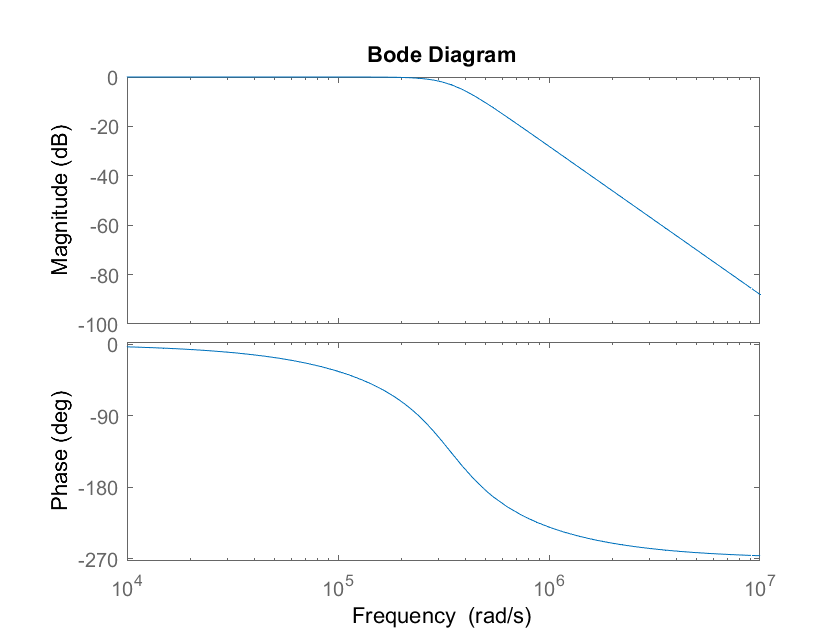

bode(filtro1); 

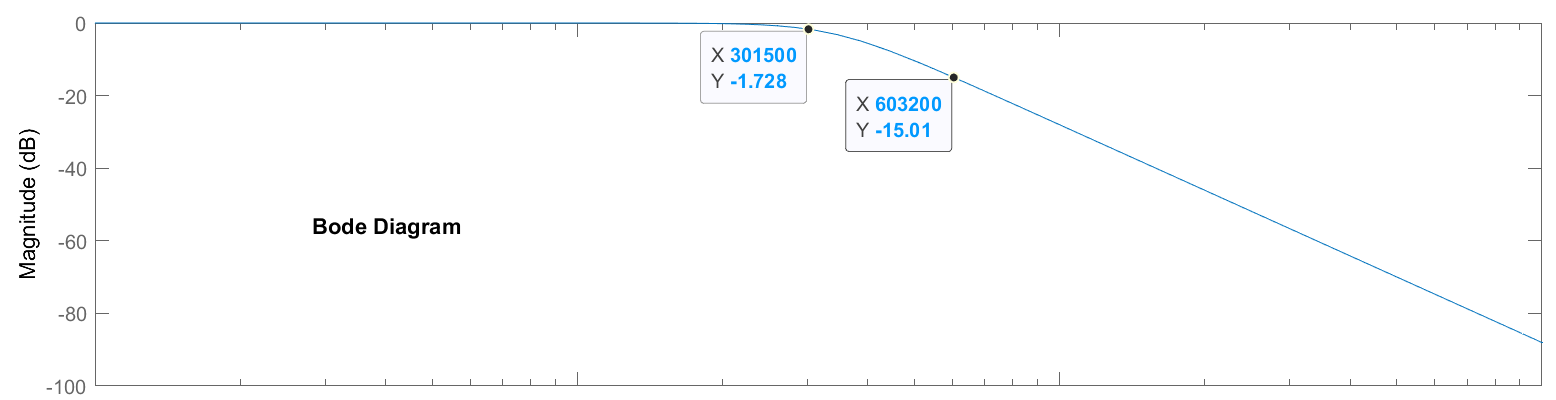

Como se observa en la figura anterior, se cumplen las especificaciones solicitadas.

### Filtro Analógico de Butterworth Pasabandas

Con las especificaciones dadas tenemos que: 

%Definición Características
Rp2 = 3; 
WB2 = 2*pi*96000;
WB3 = 2*pi*120000;
As2 = 30;
WBPB1 = [WB2 WB3]; 
WBPB2 = [WB2/2 2*WB3]; 

%Orden del filtro
[N2, W2] = buttord(WBPB1, WBPB2, Rp2, As2, 's');

%Diseño del filtro
[b2, a2] = butter (N2, W2,'bandpass','s');

%Filtro implementado como sistema
filtro2 = tf(b2,a2);

Ahora verificamos el correcto diseño del filtro graficando la magnitud y fase de su función de transferencia: 

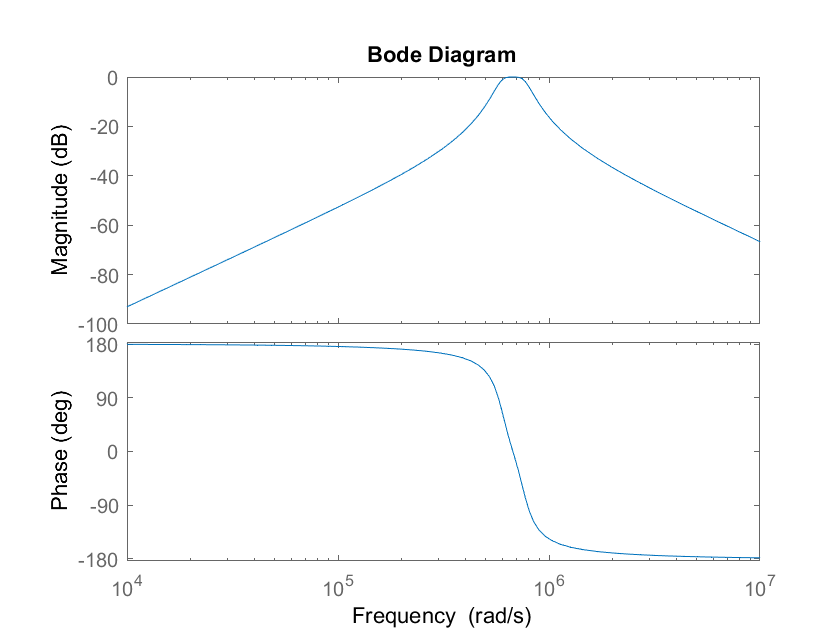

bode(filtro2); 

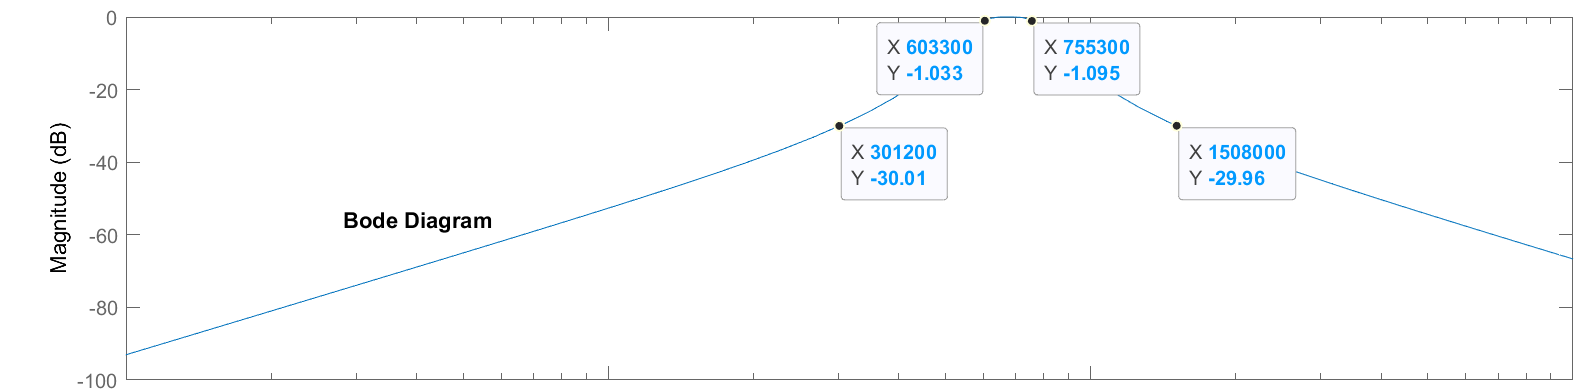

Se observa que la atenuación en la banda de paso es buena y en la banda de rechazo varia un poco en la frecuencia más alta pero aún así es muy cercana a los 30 dB, por lo cual se satisfacen las especificaciones dadas para este filtro. 

## Diseño de filtros digitales.

### Filtro Digital FIR Pasabajos

Primero, calculamos el orden del filtro FIR por medio de la aproximación de Harris: 

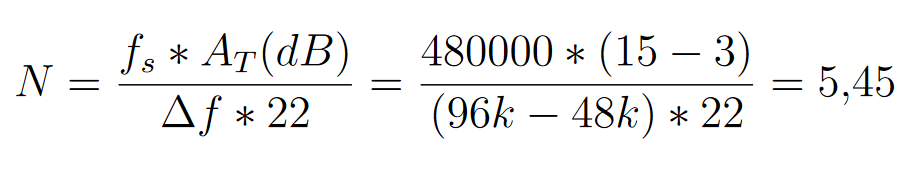

Aproximando hacia arriba y dando un mayor rango, seleccionamos: **N=6.** 

La función de Matlab para crear el filtro FIR solicita la frecuencia normalizada por lo que utilizamos la siguiente relación: 

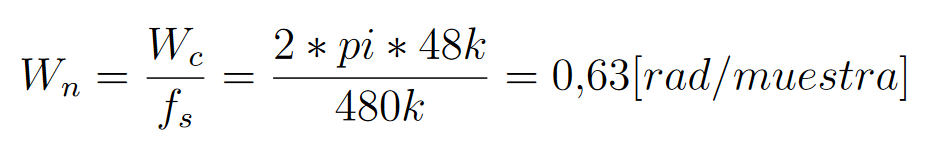

Como necesitamos atenuar 15 dB en la banda de rechazo utilizamos una ventana de Bartlett. 

**NOTA:** La función de Matlab diseña un filtro FIR con 6 dB de atenuación en Wn. 

%Definición Caracteristicas
N3 = 6; 
Wn = 1/5; 

%Diseño de la ventana
WBAR = bartlett(N3+1); 

%Diseño del filtro
FIR1 = fir1(N3, Wn,"low",WBAR); 

Ahora verificamos el correcto diseño del filtro graficando la magnitud y fase de su función de transferencia: 

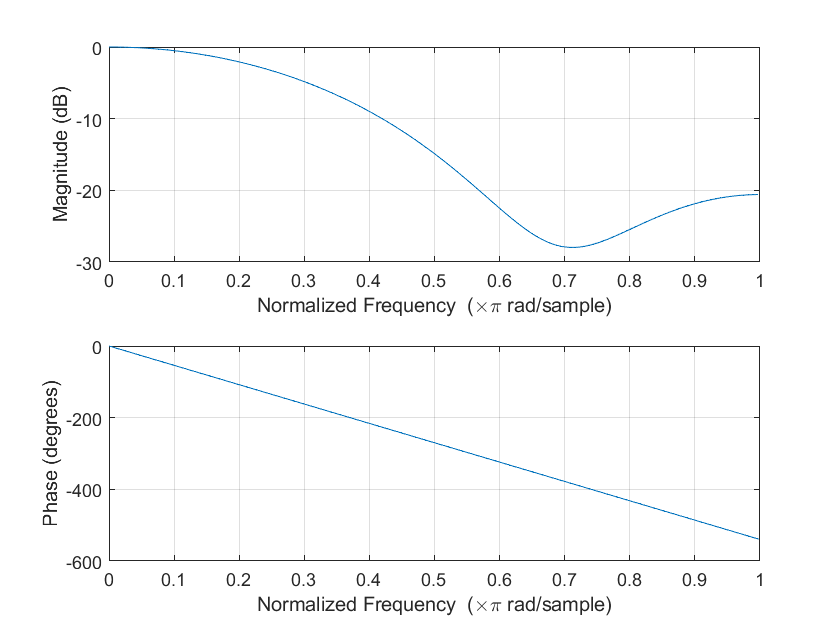

freqz(FIR1,1);

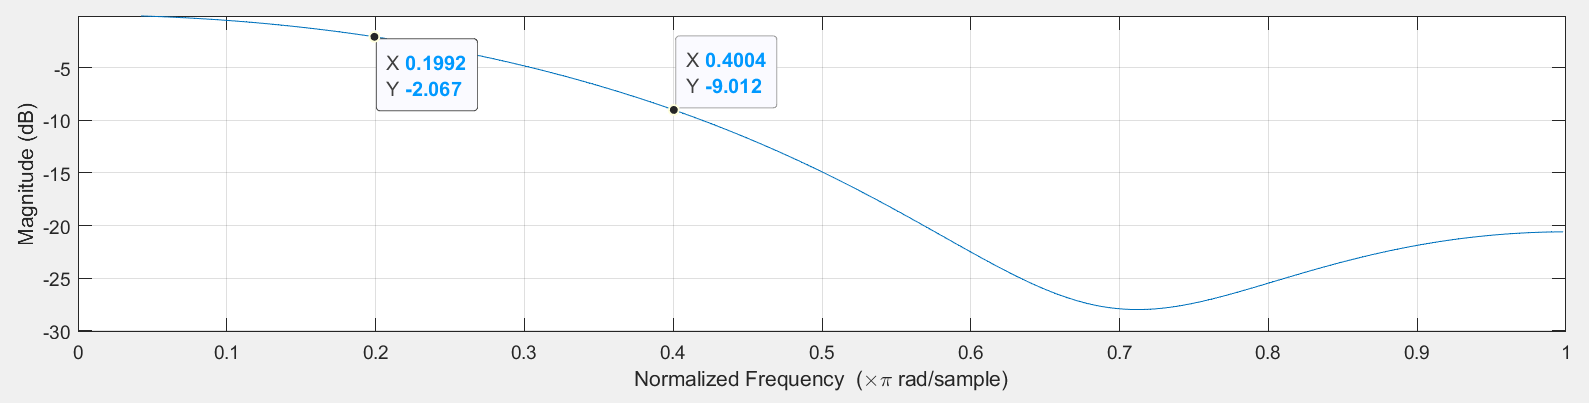 

En la figura se puede observar que en la banda de rechazo no se alcanza la atenuación solicitada, por lo tanto, por medio de ensayo y error empezamos a aumentar el orden del filtro hasta lograr el objetivo. 

%Definición Caracteristicas
N31 = 9; 

%Diseño de la ventana
WBAR1 = bartlett(N31+1); 

%Diseño del filtro
FIR11 = fir1(N31, Wn,"low",WBAR1); 

Con lo cual se obtiene: 

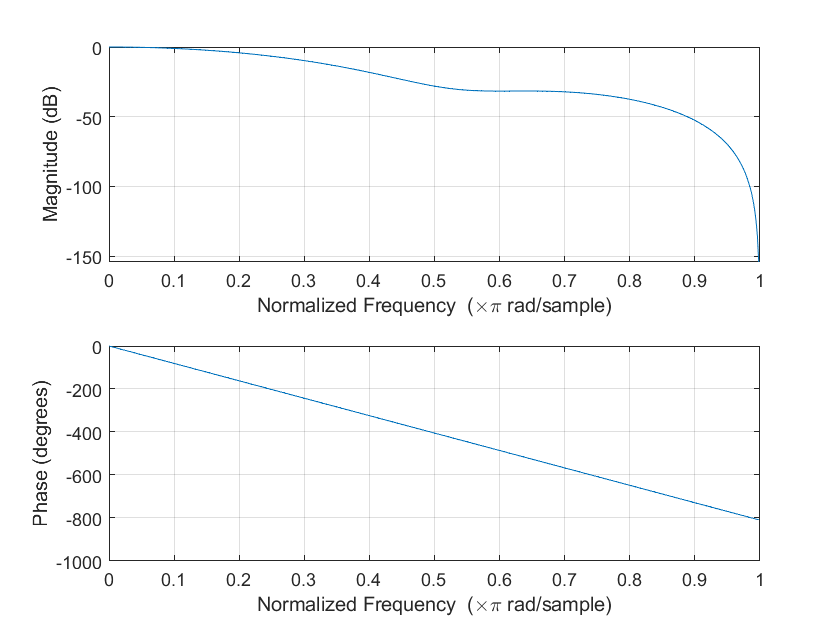

freqz(FIR11,1);

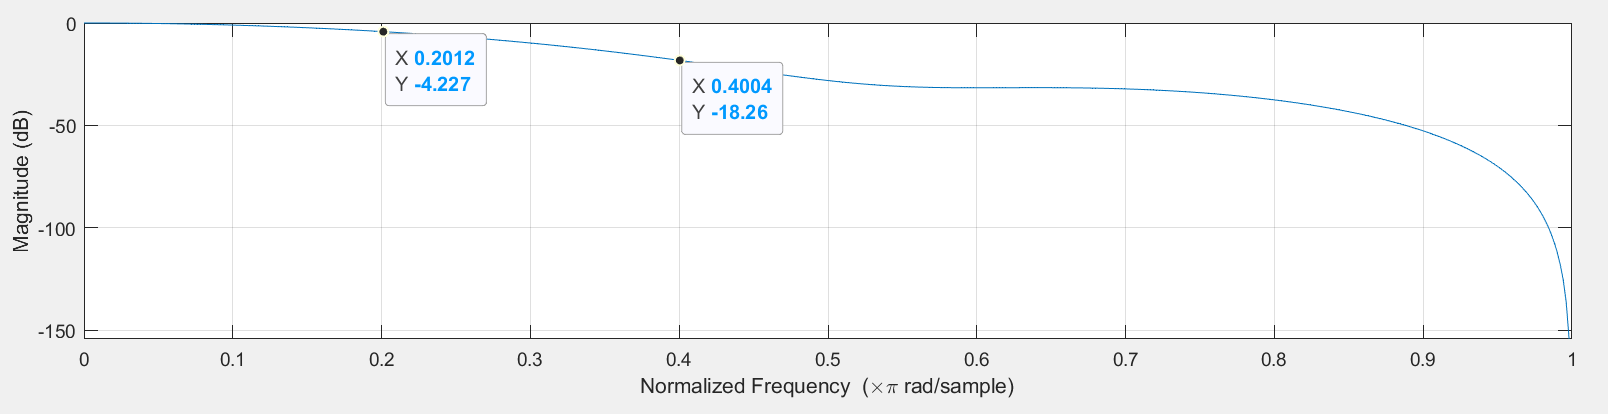

Como se observa, las especificaciones dadas, teniendo en cuenta la **NOTA** del encabezado, se cumplen satisfactoriamente. 

### Filtro Digital FIR Pasabanda

Primero, calculamos el orden del filtro FIR por medio de la aproximación de Harris: 

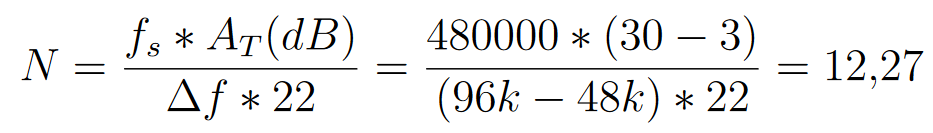

El doble de este resultado es el que nos sirve para el filtro pasabandas, es decir, el orden a utilizar será: **N=25**. 

La función de Matlab para crear el filtro FIR solicita la frecuencia normalizada por lo que utilizamos la siguiente relación: 

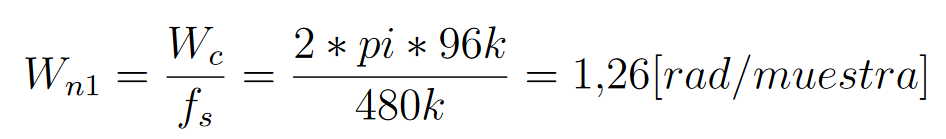

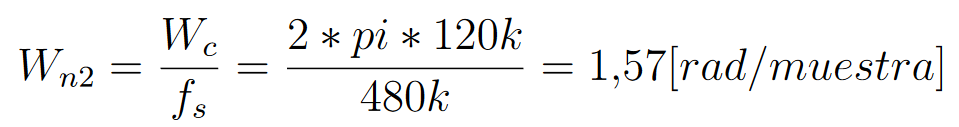

Como necesitamos atenuar 30 dB en la banda de rechazo la ventana de Hanning puede quedar muy justa, por lo que utilizamos la ventana de Hamming. 

%Definición Caracteristicas
N4 = 25; 
Wn1 = [2/5 1/2];  
WHAM = hamming(N4+1); 

%Diseño del filtro
FIR2 = fir1(N4, Wn1,"bandpass",WHAM); 

Ahora verificamos el correcto diseño del filtro graficando la magnitud y fase de su función de transferencia: 

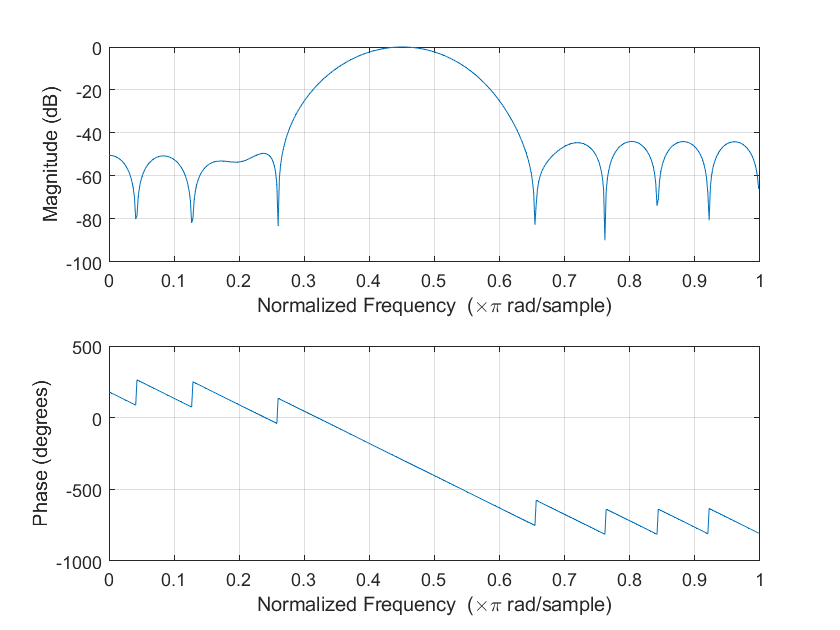

freqz(FIR2,1);

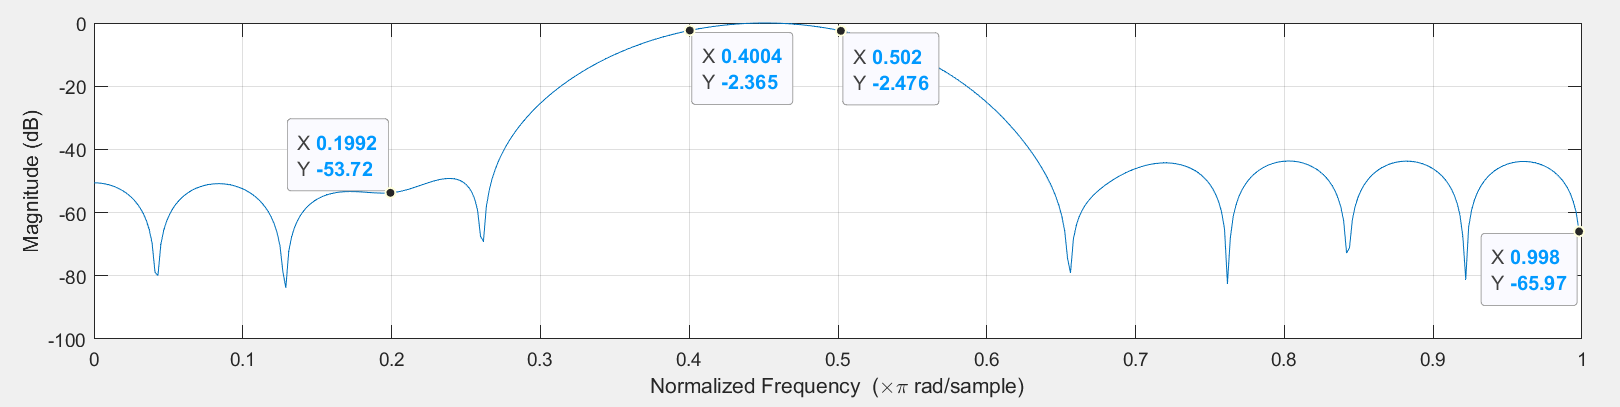

Como se puede observar, se cumplen las especificaciones para la banda de paso como para la banda de rechazo. Además, los lobulos nunca sobrepasan el limite de los 30 dB, por lo que se garantiza la atenuación en la banda de rechazo. 

## Filtros Digitales IIR 

Para este tipo de filtros, obtenemos respuestas simétricas y periódicas. Se pueden crear a partir de las especificaciones de un filtro analógico. Se diferencian en gran medida de este tipo de filtros porque se trabajan en tiempo discreto.

Para el diseño, dado que ya partimos de frecuencias analógicas, no es necesaria una conversión de digital a analógico. Pero, una vez diseñado nuestro filtro analógico, se tienen 2 métodos para su respectiva conversión a digital, luego, los métodos que se puede usar son: Invarianza del Impulso y Transformación Bilineal.

El método de Invarianza del Impulso es exclusivo para transformar filtros pasabajos y pasabanda, lo cual es ideal para cumplir nuestro objetivo de transformación. Sin embargo no sirven para tranformar pasaaltos o rechazabanda, por lo que existe un método poco lineal que permite transformar cualquier tipo de filtro analógico a digital, este método es el de Transformación Bilineal.

### Pasabajos - Invarianza de Impulso

Con las especificaciones dadas tenemos que: 

% Definición de Características
Rpa1 = 3;
WA1 = 96000*pi; 
Asa1 = 15;
WA2 = 192000*pi;

% Definición del periodo de muestreo
T1 = 1/480000;

% Cálculo del filtro analógico
[N5, Wc5] = buttord(WA1, WA2, Rpa1, Asa1, 's'); 
[B5, A5] = butter(N5, Wc5, 'low', 's'); % T.F

% Conversión por Invarianza del Impulso a Digital
[BD5, AD5] = impinvar (B5, A5, 1/T1);

Ahora verificamos el correcto diseño del filtro graficando la magnitud y fase de su función de transferencia: 

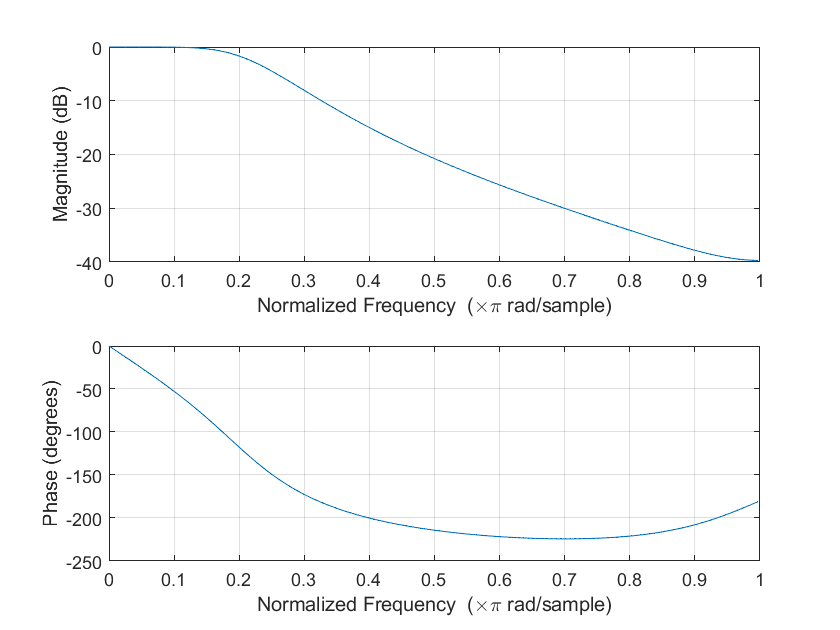

freqz(BD5, AD5)

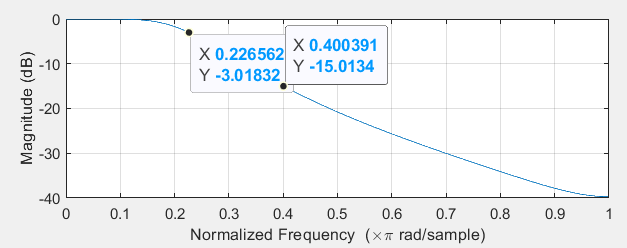

Como era de esperarse, se obtiene una respuesta óptima. Se evidencia que el eje de frecuencias está normalizado a pi radianes por muestra, con un rango de valores entre 0 y 1. Cada valor de frecuencia digital tiene su respectivo equivalente de respuesta analógica. Para hacer la comparación, debemos multiplicar la frecuencia digital mostrada en el diagrama por 240000, el cual es la mitad de la frecuancia de muestreo.

En el caso del pasabajos, la frecuencia límite de la banda de rechazo es casi exacta mientras que la frecuencia de corte alto varía un poco respecto a la deseada, esto se obtiene, dado que se partió de un filtro Butterworth, el cual fija uno de esos dos límites y varía un poco el valor del otro.

### Pasabanda - Invarianza de Impulso

% Definición de Características
Rpa2 = 3;
WAB1 = [192000*pi, 240000*pi] 

WAB1 = 	1.0e+05 *

    6.0319    7.5398


Asa2 = 30;
WAB2 = [96000*pi, 480000*pi];

% Definición del periodo de muestreo
T2 = 1/480000;

% Cálculo del filtro analógico
[N6, Wc6] = buttord(WAB1, WAB2, Rpa2, Asa2, 's');
[B6, A6] = butter(N6, Wc6, "bandpass","s");

% Conversión por Invarianza del Impulso a Digital
[BD6, AD6] = impinvar (B6, A6, 1/T2);

Ahora verificamos el correcto diseño del filtro graficando la magnitud y fase de su función de transferencia: 

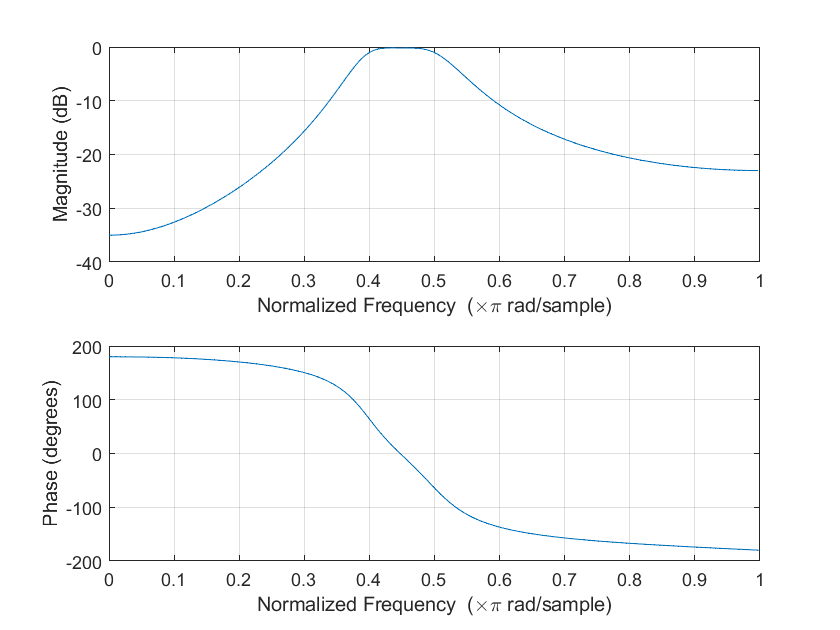

freqz(BD6, AD6)

## 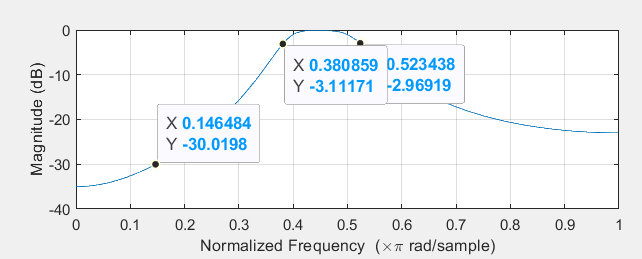

Nuevamente, logramos un resultado muy cercano al esperado, con una gráfica igualmente normalizada que el pasabanda.

### Pasabajos - Transformación Bilineal

Con las especificaciones dadas tenemos que: 

% Definición de Características
Rpa3 = 3;
WA3 = 96000*pi; 
Asa3 = 15;
WA4 = 192000*pi;

% Definición del periodo de muestreo
T3 = 1/480000;

% Cálculo del filtro analógico
[N7, Wc7] = buttord(WA3, WA4, Rpa3, Asa3, 's'); 
[B7, A7] = butter(N7, Wc7, 'low', 's'); % T.F

% Conversión por Transformación Bilinear a Digital
[BD7, AD7] = bilinear (B7, A7, 1/T3);

Ahora verificamos el correcto diseño del filtro graficando la magnitud y fase de su función de transferencia: 

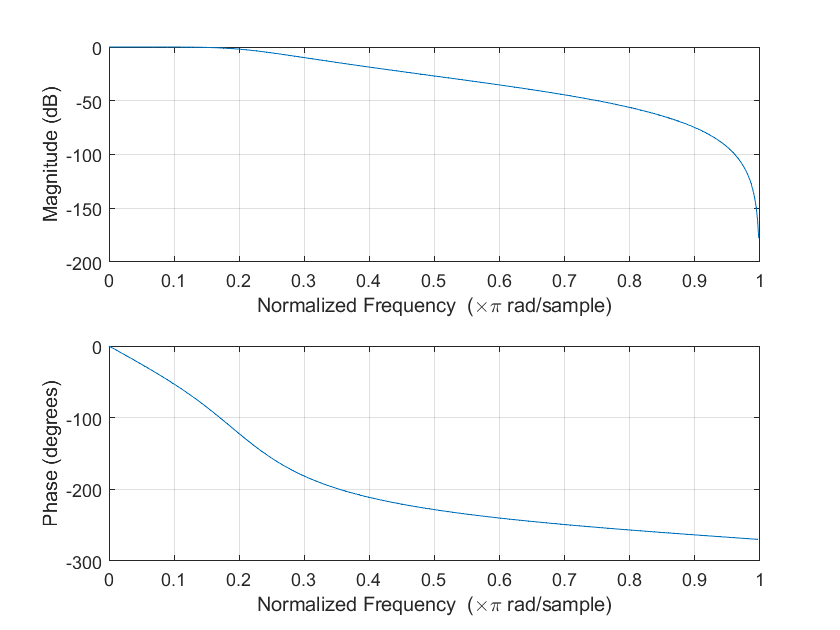

freqz(BD7, AD7)

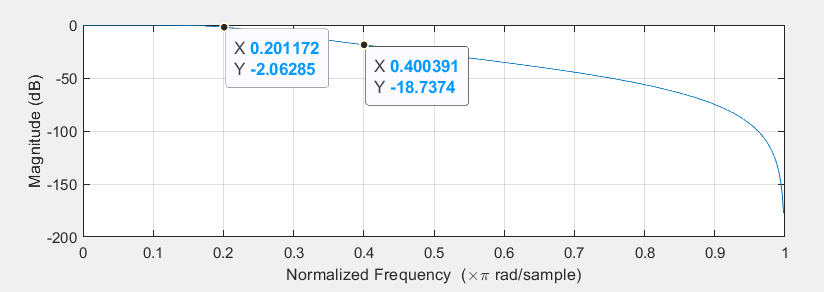

Se evidencia como este filtro toma todo el eje de frecuencias y lo transforma en el eje de frecuencias digital. De esta forma, el filtro tiene caídas muy rápidas, presentando atenuaciones muy grandes. Así, al momento de llegar a pi, la atenuación teóricamente debe ser infinita.

Nuevamente, dada la forma en la que se realizó el muestreo, tenemos nuestro eje dividido de 0 a 1, donde 1 es la mitad de nuestra frecuencia de muestreo, es decir, 240000.

Así, en comparación con su contraparte lineal por Invarianza del Impulso, el filtro por Transformación Bilineal presenta atenuaciones mucho mayores.

### Pasabanda - Transformación Bilineal

Con las especificaciones dadas tenemos que: 

% Definición de Características
WAB3 = [192000*pi, 240000*pi];
WAB4 = [96000*pi, 480000*pi];
Rpa4 = 3;
Asa4 = 30;

% Definicón frecuencia de muestreo
fs = 480000;
frec = WAB3/fs;

% Cálculo del filtro analógico
[N8, Wc8] = buttord(WAB3, WAB4, Rpa4, Asa4, 's');
[B2, A2] = butter(N8, Wc8, 's');

% Definición de la frecuencia de muestreo
f_f1 = WAB3(1)/(2*tan(0.5*frec(1)));
f_f2 = WAB3(2)/(2*tan(0.5*frec(2)));
f_filtro = sqrt(f_f1*f_f2);

% Conversión por Transformación Bilinear a Digital
[BD8, AD8] = bilinear(B2, A2, f_filtro);

Ahora verificamos el correcto diseño del filtro graficando la magnitud y fase de su función de transferencia: 

freqz(BD8, AD8)

## 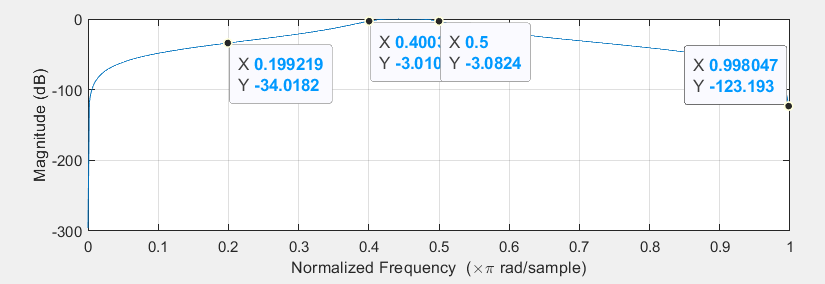

## Diseño de las diferentes versiones del sistema. 

Las señales que se utilizaran en los diferentes sistemas son: 

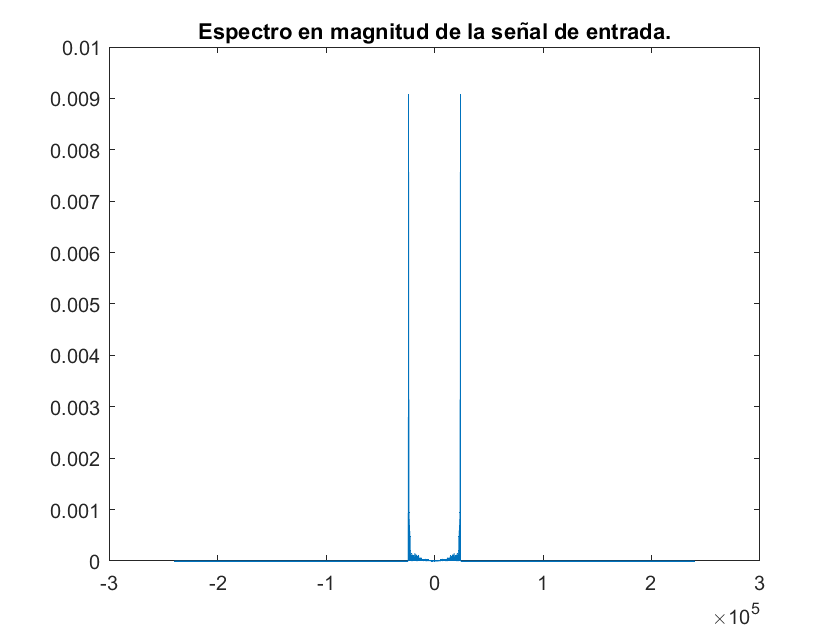

%Señal de entrada
load('Prueba.mat', 'Codificada');
x = Codificada';
time = linspace(0,10,4800000);
fs = 480000;

%Espectro en magnitud de la señal de entrada
FFT_x = fftshift(fft(x))/length(x); 
omega = linspace(-fs/2, fs/2, length(FFT_x)); 
magnitude_x = abs(FFT_x); 

figure('NAME','Espectro en magnitud de la señal de entrada'); 
plot(omega, magnitude_x); 
title('Espectro en magnitud de la señal de entrada.');


%Señales Auxiliares
s1 = 2*cos(WB3.*time); 
s2 = 2*cos(WB2.*time); 

### Primera versión del sistema

En este caso, el sistema hace uso de los filtros analógicos diseñados anteriormente: 

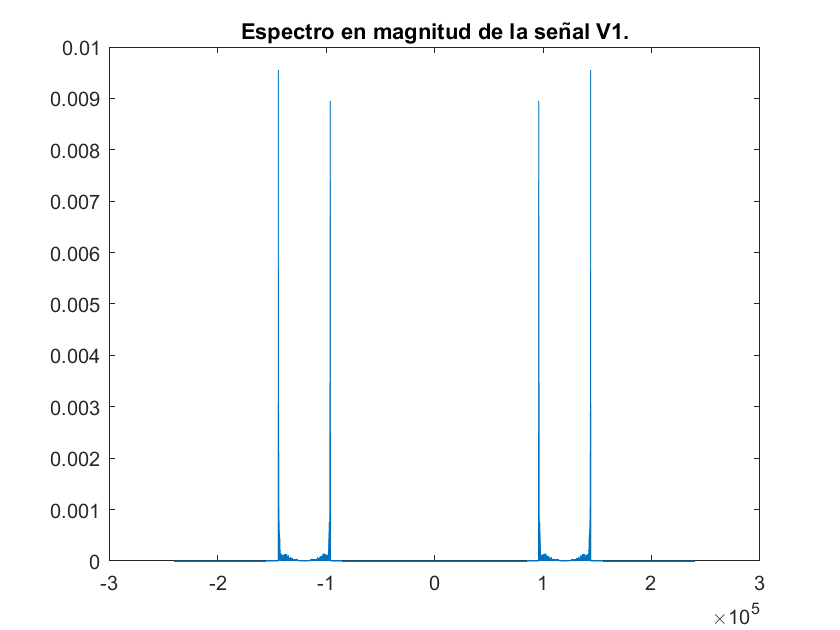

%Entrada primer filtro
v1 = x.*s1;

%Espectro en magnitud de la señal V1
FFT_v1 = fftshift(fft(v1))/length(v1);  
magnitude_v1 = abs(FFT_v1); 

figure('NAME','Espectro en magnitud de la señal V1'); 
plot(omega, magnitude_v1); 
title('Espectro en magnitud de la señal V1.');



%Salida primer filtro
w1 = lsim(filtro2,v1,time); 

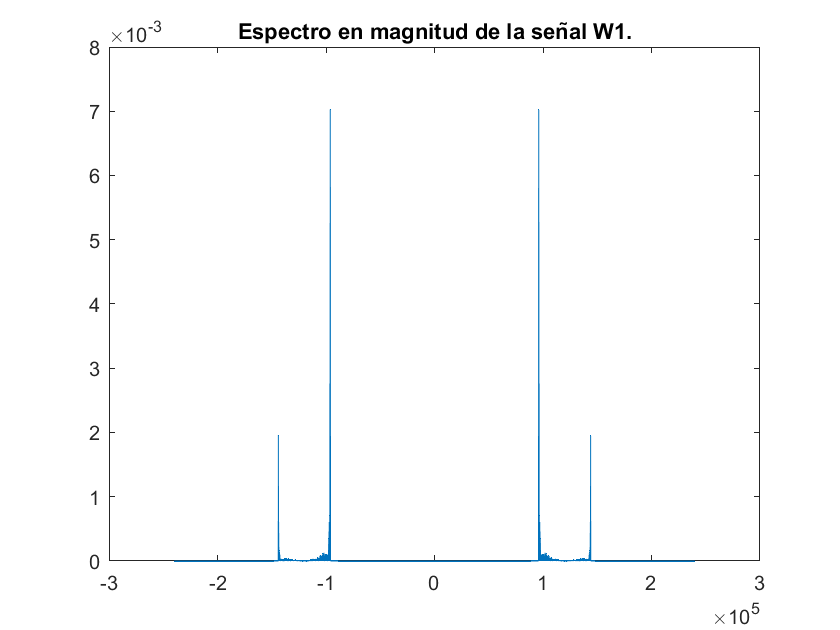

w1 = w1';

%Espectro en magnitud de la señal W1
FFT_w1 = fftshift(fft(w1))/length(w1);  
magnitude_w1 = abs(FFT_w1); 

figure('NAME','Espectro en magnitud de la señal W1'); 
plot(omega, magnitude_w1); 
title('Espectro en magnitud de la señal W1.');

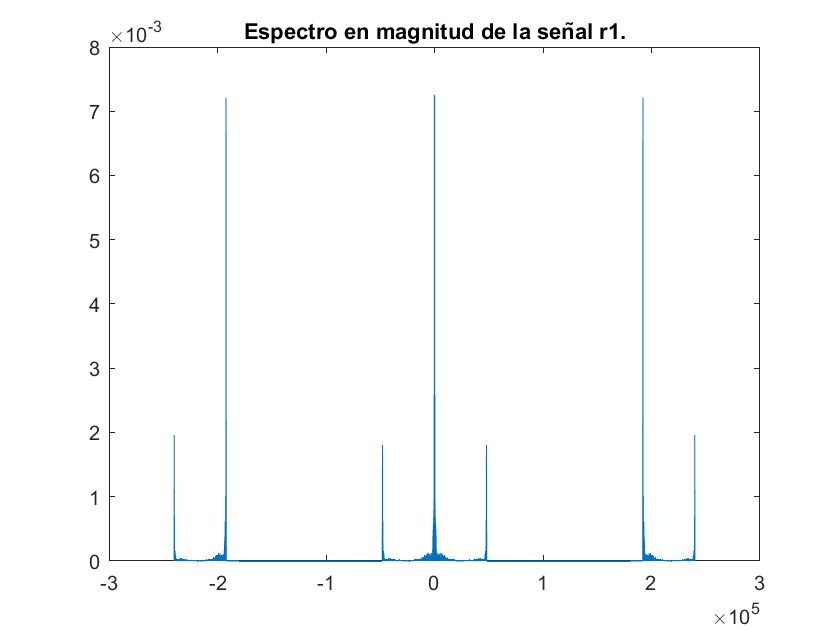



%Entrada segundo filtro
r1 = w1.*s2; 

%Espectro en magnitud de la señal r1
FFT_r1 = fftshift(fft(r1))/length(r1);  
magnitude_r1 = abs(FFT_r1); 

figure('NAME','Espectro en magnitud de la señal r1'); 
plot(omega, magnitude_r1); 
title('Espectro en magnitud de la señal r1.');

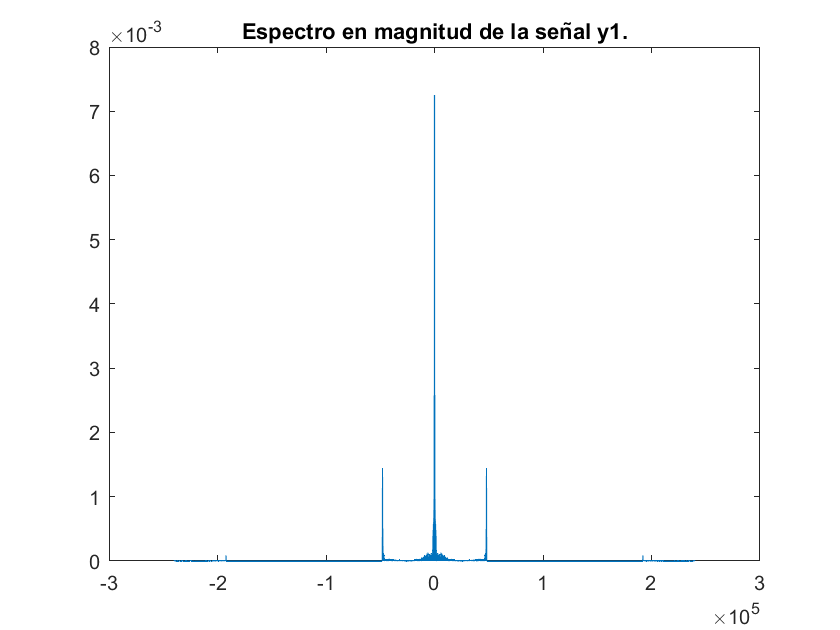


%Salida segundo filtro / Salida final
y1 = lsim(filtro1,r1,time); 
y1 = y1'; 

%Espectro en magnitud de la señal final
FFT_y1 = fftshift(fft(y1))/length(y1);  
magnitude_y1 = abs(FFT_y1); 

figure('NAME','Espectro en magnitud de la señal y1'); 
plot(omega, magnitude_y1); 
title('Espectro en magnitud de la señal y1.');


%Prueba de la salida del sistema 
YD1 = decimate(y1,10);
sound(YD1, 48000);
pause(11);

### Segunda versión del sistema

En este caso, el sistema hace uso de los filtros digitales FIR diseñados anteriormente: 

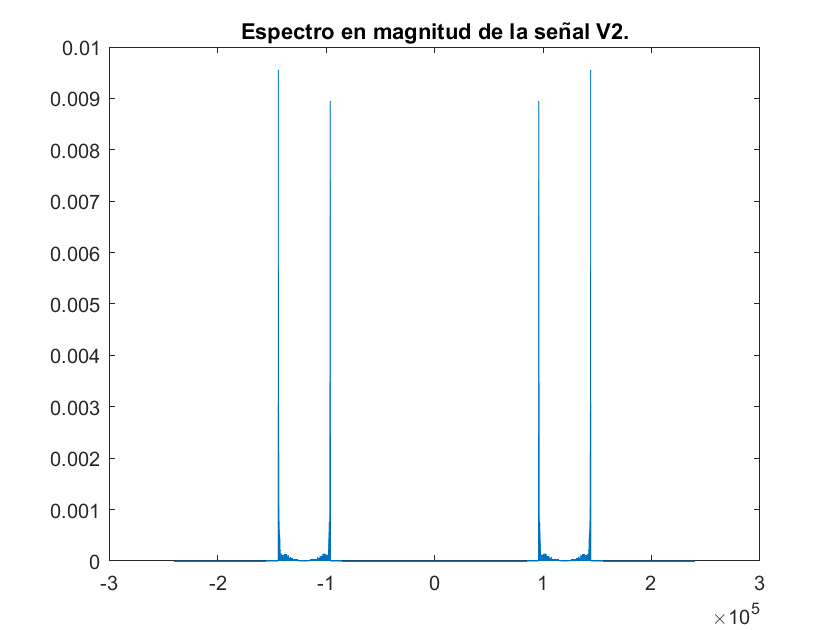

%Entrada primer filtro
v2 = x.*s1;

%Espectro en magnitud de la señal V2
FFT_v2 = fftshift(fft(v2))/length(v2);  
magnitude_v2 = abs(FFT_v2); 

figure('NAME','Espectro en magnitud de la señal V2'); 
plot(omega, magnitude_v2); 
title('Espectro en magnitud de la señal V2.');

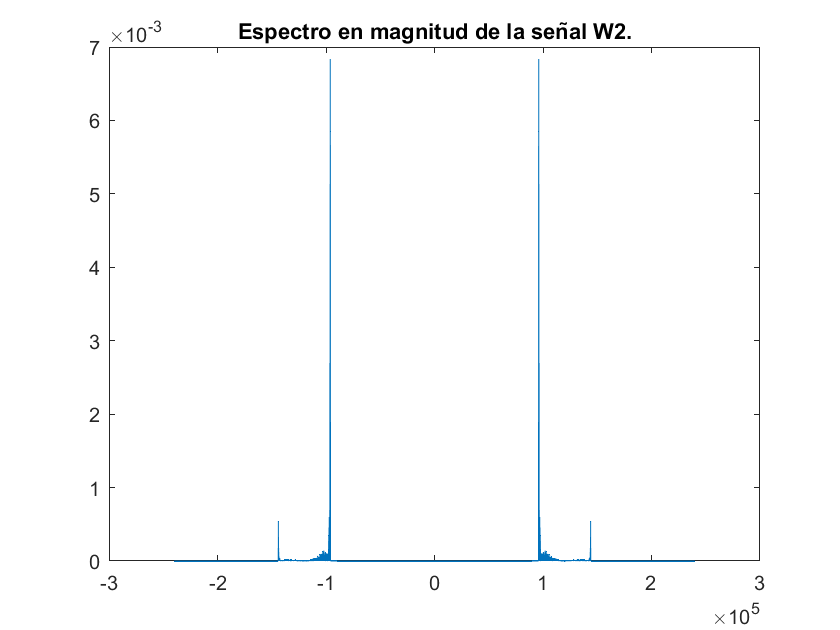



%Salida primer filtro
w2 = fftfilt(FIR2,v2); 

%Espectro en magnitud de la señal W1
FFT_w2 = fftshift(fft(w2))/length(w2);  
magnitude_w2 = abs(FFT_w2); 

figure('NAME','Espectro en magnitud de la señal W2'); 
plot(omega, magnitude_w2); 
title('Espectro en magnitud de la señal W2.');

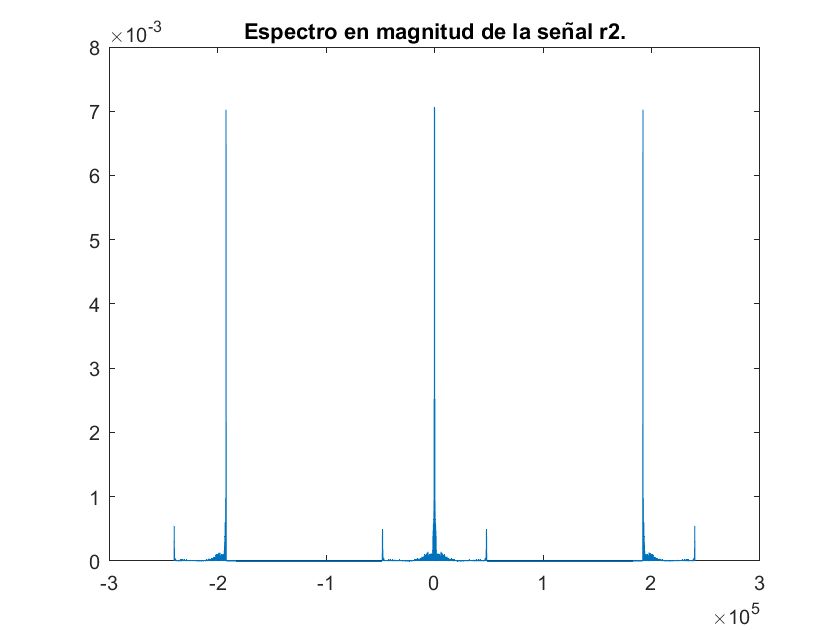



%Entrada segundo filtro
r2 = w2.*s2; 

%Espectro en magnitud de la señal r1
FFT_r2 = fftshift(fft(r2))/length(r2);  
magnitude_r2 = abs(FFT_r2); 

figure('NAME','Espectro en magnitud de la señal r2'); 
plot(omega, magnitude_r2); 
title('Espectro en magnitud de la señal r2.');

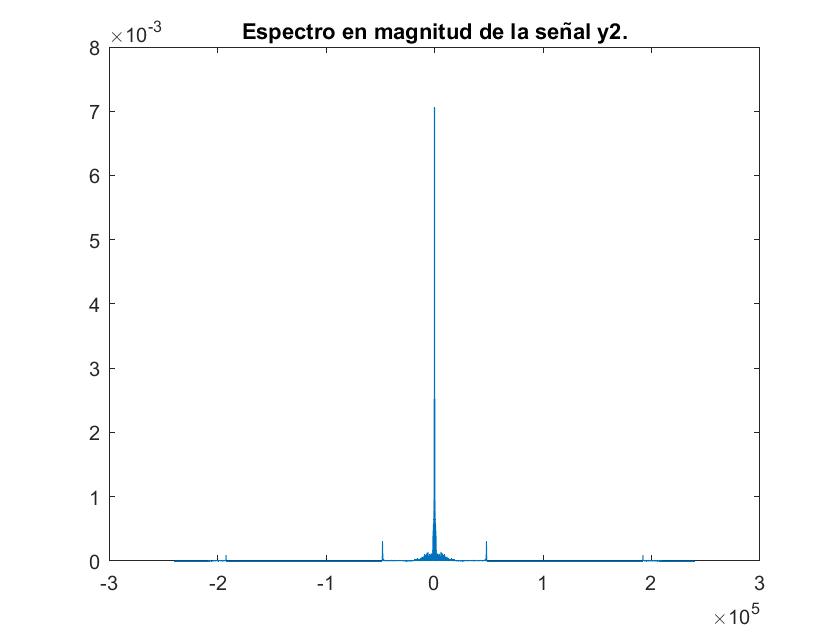


%Salida segundo filtro / Salida final
y2 = fftfilt(FIR11,r2); 
y2 = y2'; 

%Espectro en magnitud de la señal final
FFT_y2 = fftshift(fft(y2))/length(y2);  
magnitude_y2 = abs(FFT_y2); 

figure('NAME','Espectro en magnitud de la señal y2'); 
plot(omega, magnitude_y2); 
title('Espectro en magnitud de la señal y2.');

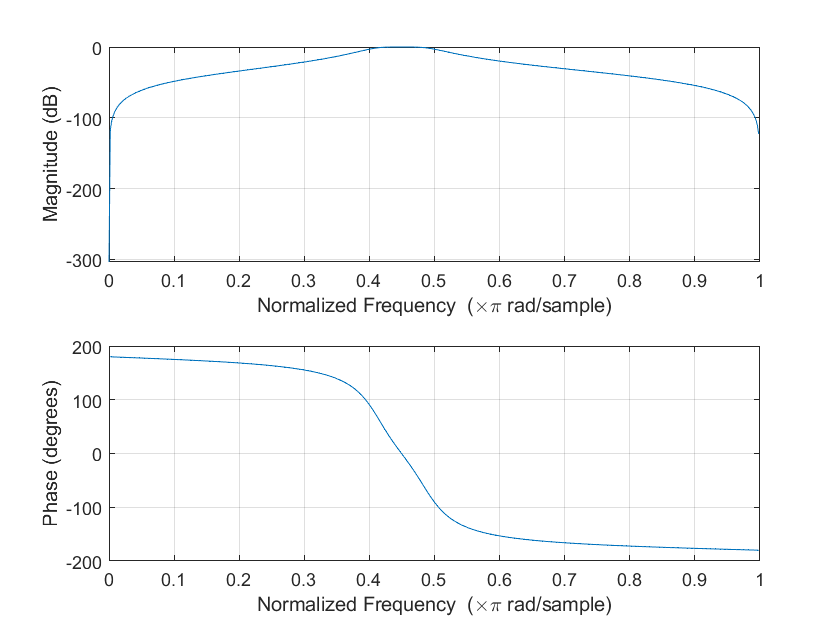


%Prueba de la salida del sistema 
YD2 = decimate(y2,10);
sound(YD2, 48000);
pause(11);

### Tercera versión del sistema

En este caso, se utilizaron los filtros de Invarianza del Impulso, dado que dan un mejor margen de atenuacion que los de Transformación Bilineal, pues estos últimos, al tener valores tan exactos (principalmente en el pasabanda) ante una variación mínima de los parámetros, podrían fallar.

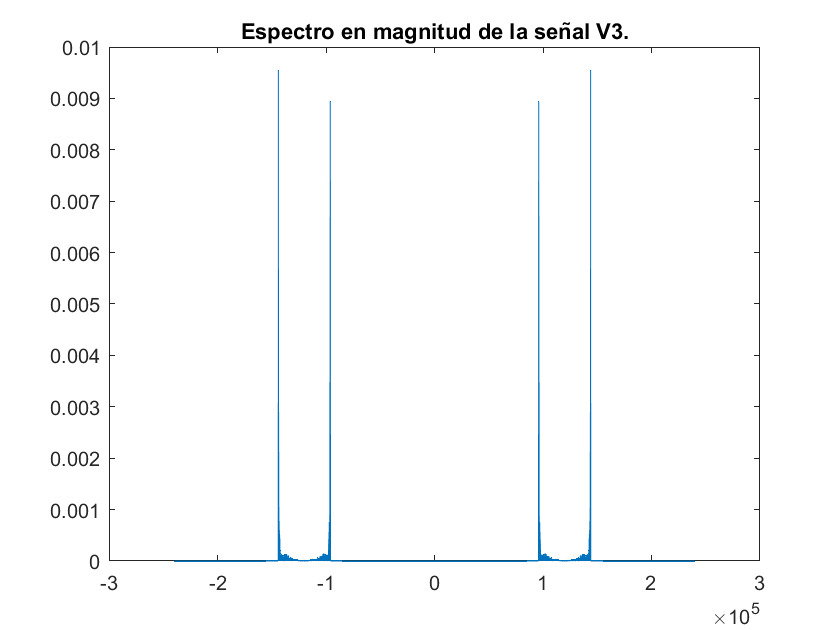

%Entrada primer filtro
v3 = x.*s1;

%Espectro en magnitud de la señal V3
FFT_v3 = fftshift(fft(v3))/length(v3);  
magnitude_v3 = abs(FFT_v3); 

figure('NAME','Espectro en magnitud de la señal V3'); 
plot(omega, magnitude_v3); 
title('Espectro en magnitud de la señal V3.');

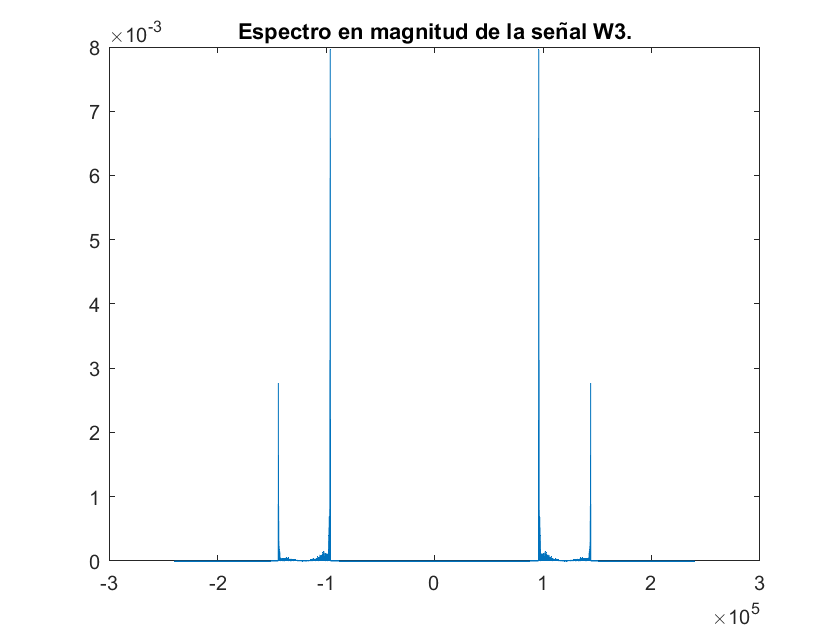



%Salida primer filtro

w3 = filter(BD6,AD6,v3); 

%Espectro en magnitud de la señal W3
FFT_w3 = fftshift(fft(w3))/length(w3);  
magnitude_w3 = abs(FFT_w3); 

figure('NAME','Espectro en magnitud de la señal W3'); 
plot(omega, magnitude_w3); 
title('Espectro en magnitud de la señal W3.');

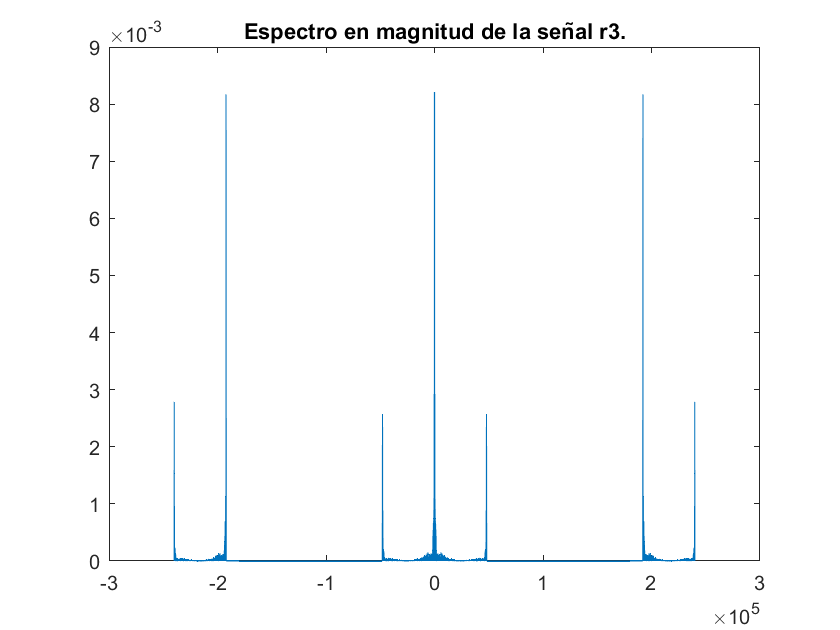



%Entrada segundo filtro
r3 = w3.*s2; 

%Espectro en magnitud de la señal r3
FFT_r3 = fftshift(fft(r3))/length(r3);  
magnitude_r3 = abs(FFT_r3); 

figure('NAME','Espectro en magnitud de la señal r3'); 
plot(omega, magnitude_r3); 
title('Espectro en magnitud de la señal r3.');

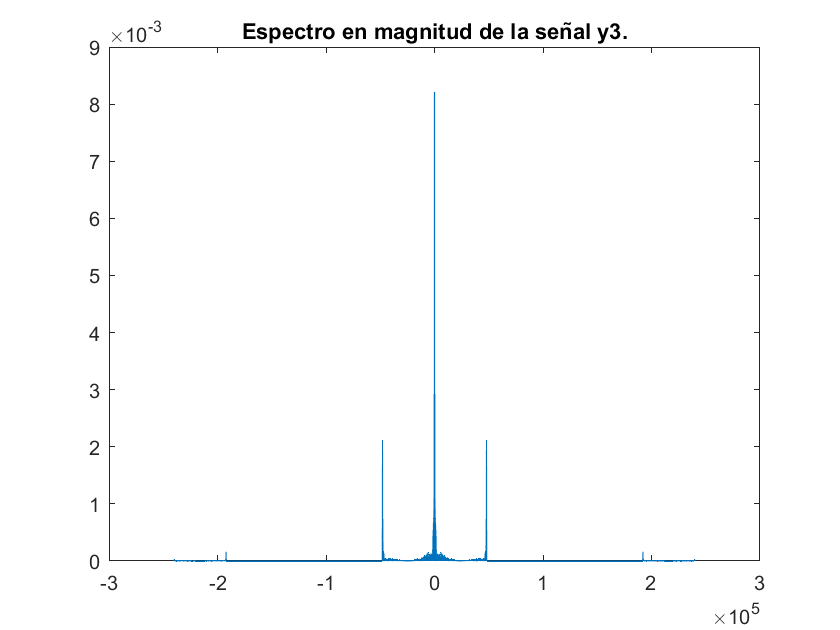


%Salida segundo filtro / Salida final
y3 = filter(BD5, AD5, r3); 
y3 = y3'; 

%Espectro en magnitud de la señal final
FFT_y3 = fftshift(fft(y3))/length(y3);  
magnitude_y3 = abs(FFT_y3); 

figure('NAME','Espectro en magnitud de la señal y3'); 
plot(omega, magnitude_y3); 
title('Espectro en magnitud de la señal y3.');


%Prueba de la salida del sistema 
YD3 = decimate(y3,10);
sound(YD3, 48000);
pause(11); 